# Runge Kutta method of 4th order

clear all, clc

%Initial conditions
t(1) = 0;
x(1) = 20.085;

% simulation parameters
t_f = 1 ;  
h = .1;  % step size

f = @(x,t) (-t+ 0.25)*x   % Function to be integrated or ODE in RHS 

f = function_handle with value:
    @(x,t)(-t+0.25)*x


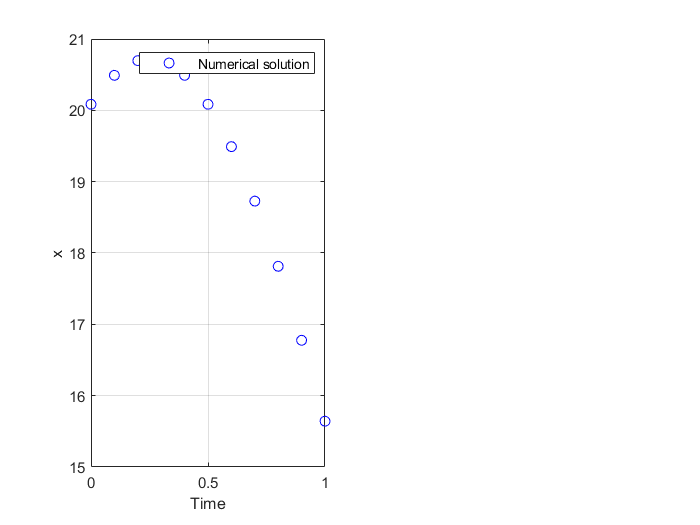


% RK 4 loop

for i= 1:ceil(t_f/h)
    
    %update t
    t(i+1) = t(i) + h;
    
    %update x
    s1 = h*f(x(i),t(i));
    s2 = h*f(x(i) + 0.5*s1, t(i) + 0.5*h);
    s3 = h*f(x(i) + 0.5*s2, t(i) + 0.5*h);
    s4 = h*f(x(i) + s3, t(i) + h);
    
    x(i+1) = x(i) + 1/6 *(s1 + 2*s2 + 2*s3 + s4);
end

figure(1)
subplot(1,2,1)
plot(t,x, 'bo')
legend('Numerical solution')
grid on , hold on
xlabel('Time')
ylabel('x')

## classical solution

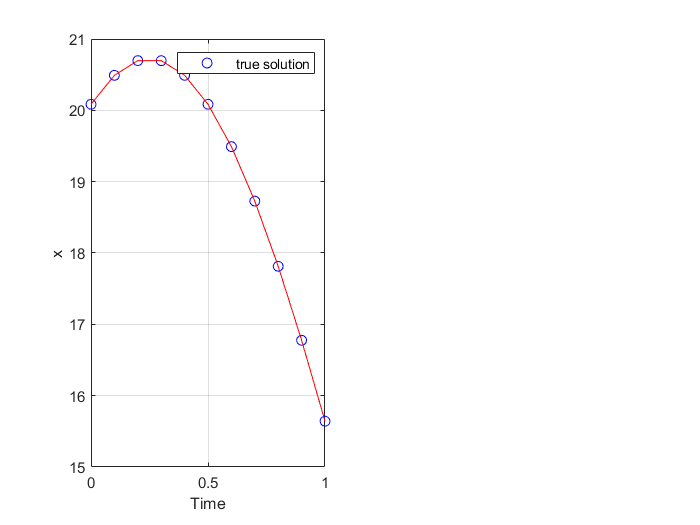

subplot(1,2,1)
g = exp(-0.5.*t.^2 +.25*t+3.0);
plot(t,g,'r')
grid on , hold on
xlabel('Time')
ylabel('x')
legend('true solution')